parallel.gpu.enableCUDAForwardCompatibility(true)

ir_len = 128;
source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);

[target, ref] = recorded_samples();

filter_order = ir_len * 2;
n_iter = 10;

% mu = 0.05;
% fxlms = FxLMS(ref, target, panel_ir, filter_order, mu);
% fxlms.gpu = false;

% [pred, mses] = fxlms.learn(n_iter, true);

% figure
% plot(mses);

lamda = 0.999;
cov_scale = 0.1

cov_scale = 0.1000

fxrls = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);

fxrls.gpu = false;

[pred, mses] = fxrls.learn(n_iter, true);

Iteration 1/10
Iteration 2/10
Iteration 3/10
Iteration 4/10
Iteration 5/10
Iteration 6/10
Iteration 7/10
Iteration 8/10
Iteration 9/10
Iteration 10/10


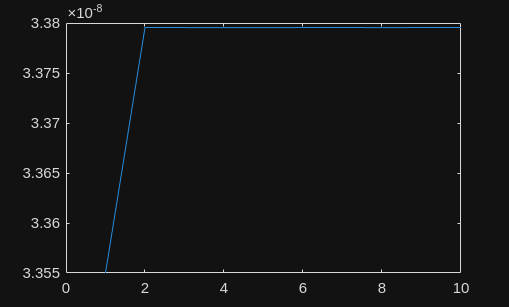

figure
plot(mses);

ir_len = 1024;
source_to_ref_cm = 2;
panel_ir = clipped_irs(ir_len, source_to_ref_cm);

filter_order = ir_len * 2;
n_iter = 2;

fxrls = FxRLS(ref, target, panel_ir, filter_order, lamda, cov_scale);
fxrls.gpu = true;

[pred, mses] = fxrls.learn(n_iter, true);

Iteration 1/2


figure
plot(mses);

fxlrs.results_plot()